## Importing all the master 'fits' files

% Imports all the master frames and contains them in a structure
% where the elements in the first column are the names and
% the elements in the second column are the matrices themselves.

master_dir = dir('*.fits');
master_names = {master_dir.name};
master_data = cell(size(master_names,2),2);
master_data(:,1) = regexprep(master_names, '.fits', '');

for i = 1:numel(master_names)
    master_data{i,2} = fitsread(master_names{i});
end

clear master_dir master_names

## Importing all the capture 'fits' files

% Imports all the image frames and contains them in a structure
% where the elements in the first column are the names and
% the elements in the second column are the matrices themselves.

frames_dir = dir('*/*.fits');
frames_names = {frames_dir.name};
frames_folder = {frames_dir.folder};
frames_data = cell(size(frames_names,2),2);
frames_data(:,1) = regexprep(frames_names, '.fits', '');

for i = 1:numel(frames_names)
    frames_data{i,2} = fitsread(strcat(frames_folder{i},'\',frames_names{i}));
    % normalize captures
    frames_data{i,2} = frames_data{i,2}/max(frames_data{i,2}(:));
end

clear frames_folder frames_names frames_dir

## Subtracting dark frame

% Selects the dark frame by finding file with work 'DARK' in name
for j = 1:size(master_data,1)
    if (contains(master_data{j,1},'DARK'))
        break;
    end
end

for i = 1:size(frames_data,1)
    frames_data{i,2} = frames_data{i,2} - (master_data{j,2});
    % Find negative intensity values
    % and replace with 0
    replace = find(frames_data{i,2} < 0);
    frames_data{i,2}(replace) = 0;
end

## Dividing out flat frame

% Selects the flat frame by finding file with work 'FLAT' in name
for j = 1:size(master_data,1)
    if (contains(master_data{j,1},'FLAT'))
        break;
    end
end

% Smoothens the frame to provide even lighting
H = ones(6,6)/36;
master_data{j,2} = conv2(master_data{j,2},H,'same');
master_data{j,2} = master_data{j,2}/max(master_data{j,2}(:));

% Scale the values from 0.75 - 1.0 so that low values do not cause
% pixel values to blow up.
master_data{j,2} = rescale(master_data{j,2},0.75,1);
for i = 1:5
    frames_data{i,2} = frames_data{i,2}./(master_data{j,2});
end

## Finding Star Blobs For Transformation 

*Not being used. Just an idea for how to align*

% tres = 0.5;
% for i = 1:5
%     temp = threshold(frames_data{i,2},tres);
% %     figure;
% %     imshow(temp);
%     conn = bwlabel(temp,4);
%     stars = [0 0 0 0 0];
%     points = [0;0];
%     for val = 1:max(conn(:))
% %         num = sum(size(find(conn == val)));
%         [r, c] = find(conn == val);
%         num = sum(size(r,1));
%         if (num >= stars(5))
%             stars(1) = stars(2);
%             stars(2) = stars(3);
%             stars(3) = stars(4);
%             stars(4) = stars(5);
%             stars(5) = val;
%         elseif (num >= stars(4))
%             stars(1) = stars(2);
%             stars(2) = stars(3);
%             stars(3) = stars(4);
%             stars(4) = val;
%         elseif (num >= stars(3))
%             stars(1) = stars(2);
%             stars(2) = stars(3);
%             stars(3) = val;
%         elseif (num >= stars(2))
%             stars(1) = stars(2);
%             stars(2) = val;
%         elseif (num >= stars(1))
%             stars(1) = val;
%         end
%     end
%     show = zeros(size(temp), 'double');
%     for j = 1:numel(temp)
%         if (conn(j) == stars(1))
%             show(j) = 1;
%         elseif (conn(j) == stars(2))
%             show(j) = 1;
%         elseif (conn(j) == stars(3))
%             show(j) = 1;
%         elseif (conn(j) == stars(4))
%             show(j) = 1;
%         elseif (conn(j) == stars(5))
%             show(j) = 1;
%         end
%     end
%     frames_data{i,3} = show;
% end
% clear stars tres val i j c r

## Image Transformation Matrices

% Picked 4 bright stars of which at least 3 appear in each image frame.
% This allows us to determine the the x and y shift each frame needs
% to match the first image frame that is being used as the reference.

% We generated x and y points by zooming in on each image and using
% the cursor to determine the position of the center of the star.

% Results of x and y positions for each image.
% In format 'image number'.'star number' so 1.4 is 1st image 4th star.
% 
% star 1.1: 257 2365
% star 1.2: 748 1936
% star 1.3: 1626 1070
% star 1.4: 1715 945
% 
% star 2.1: 262 2407
% star 2.2: 753 1978
% star 2.4: 1720 987
% 
% star 3.2: 794 1936
% star 3.3: 1672 1070
% star 3.4: 1761 945
% 
% star 4.1: 305 2411
% star 4.2: 795 1982
% star 4.3: 1673 1115
% star 4.4: 1762 990
% 
% star 5.1: 308 2455
% star 5.2: 799 2025
% star 5.3: 1676 1159
% star 5.4: 1765 1035

% Define transformation matrices
trans21 = [1 0 42; 0 1 5; 0 0 1]; % x-shift: 42 | y-shift: 5
trans31 = [1 0 0; 0 1 46; 0 0 1]; % x-shift: 0 | y-shift: 46
trans41 = [1 0 46; 0 1 47; 0 0 1]; % x-shift: 46 | y-shift: 47
trans51 = [1 0 90; 0 1 51; 0 0 1]; % x-shift: 90 | y-shift: 51

%Store all transform matrices in a cell structure
transforms = cell(4,1);
transforms{1,1} = trans21;
transforms{2,1} = trans31;
transforms{3,1} = trans41;
transforms{4,1} = trans51;

clear trans21 trans31 trans41 trans51

## Align Images

% Generate new coordinates to align images
% We iterate from 2 to 5 as first image is reference
for i = 2:5
    temp = frames_data{i,2};
    shifted = zeros(size(temp));
    for j = 1:size(temp,1)
        for k = 1:size(temp,2)
            new = transforms{i-1,1}*[j;k;1];
            % Make sure new coordinate is within size bounds of ref image
            if (new(1) >= 1 && new(1) <= size(temp,1) && new(2) >= 1 && new(2) <= size(temp,2))
                shifted(j,k) = temp(new(1),new(2));
            end
        end
    end
    frames_data{i,4} = shifted;
end

clear i temp shifted

## Stacking Images

% Stack image into one frame
summed = zeros(size(frames_data{1,2}),'double');
for i = 1:5
    if i==1
        summed = summed+frames_data{i,2};
    else
        summed = summed+frames_data{i,4};
    end
end
% Smooth final image
H = ones(3,3)/9;
summed = conv2(summed, H, 'same');

clear i H

## Histogram Equalizing

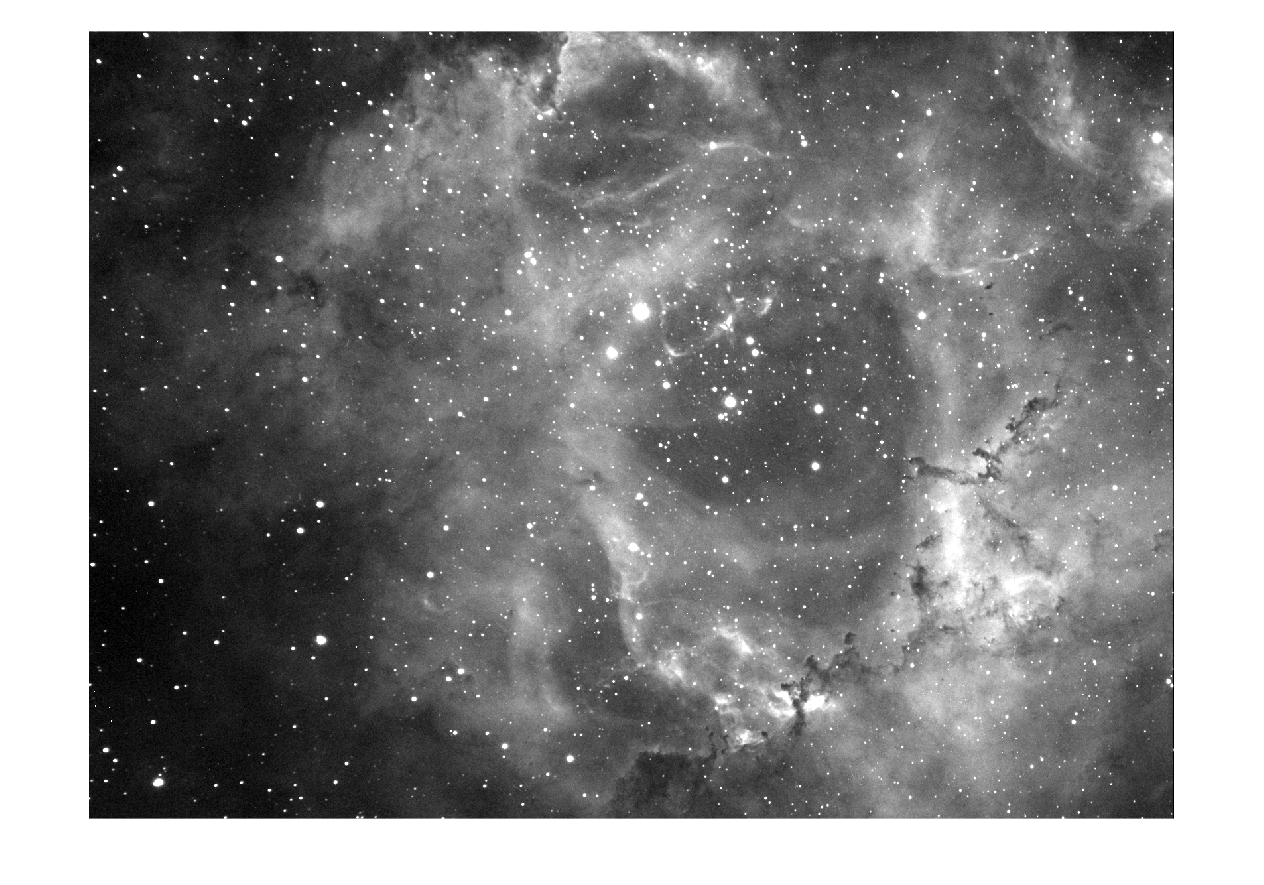

% Adjust Histogram to brighten the image
summed = adjust_img(summed,200);
% Crop the image a little to remove distortion around edges
summed = summed([100:end-100],[50:end-50]);
imshow(summed);

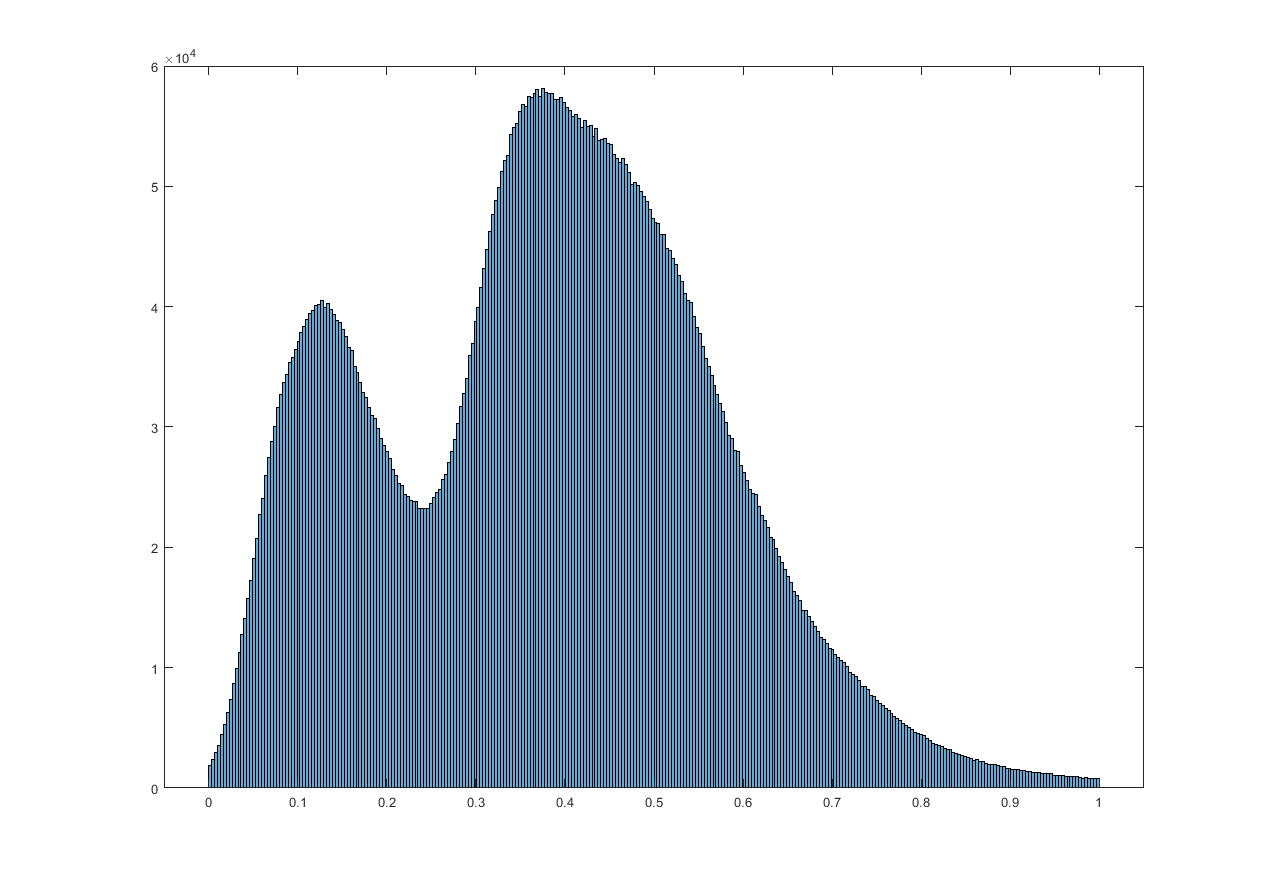

% Show histogram of image on range 0 to 1
histogram(summed,'BinLimits',[0 1]);

## Supporting Functions

function [out] = adjust_img(in,thresh)
    out = zeros(size(in),'double');
    dist = sort(in(:),'ascend');
    n = round(length(dist)/(thresh));
    low_val = dist(10*n);
    high_val = dist(end-n);
    out(:) = (1/double(high_val-low_val))*(in(:)-low_val);
    clear low_val high_val n;
end